start_time = datetime('now')

start_time = datetime
   23-Mar-2025 13:49:04


### GLCM with SVM - No Morphology

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;
  
% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\No_Morphology\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';
output_svm_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir);
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end
% Create folder for SVM
if ~exist(fullfile(output_svm_dir, 'dir'))
    mkdir(output_svm_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));

Training set: 2659 images, 2659 masks


fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

Testing set: 1140 images, 1140 masks



% Init
features_matrix= [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Go through through folder
t1 = datetime('now')

t1 = datetime
   23-Mar-2025 13:49:10



% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images

list_train_imgs = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels

list_train_lbls = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images

list_test_imgs = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre

list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

list_test_lbls = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre


% Ensure corresponding images and labels exist
if numel(list_train_imgs) ~= numel(list_train_lbls)
    warning('Mismatch in image-label count');
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    for k = 1:numel(list_train_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);
                label_window = label(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});
                % High contrast is rough terrain (landlside)
                % Low E is more randomness (lanslide distrutpins)
                % High homogeneirty is uniform areas (vegetation or stable land)

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;
                features_matrix = [features_matrix; features]; % Append row

                % Assessing label - if 10% of pix in label is 1, mark as landlside
                if sum(label_window,'all') >= (window_size*window_size/10)
                    lbl = 1; % Landlside present
                else
                    lbl = 0; % No landslide
                end
                labelsVec = [labelsVec; lbl]; % Append label
            end
        end
        if ismember(k, 500:500:numel(list_train_imgs))
            t3 = datetime('now');
            elapsedTime = seconds(t3-t2); % Cacluate elapsed times
            fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);   
            t2 = datetime('now');
        end
    end
end

t2 = datetime
   23-Mar-2025 13:49:12


Total processing time after 500 imgs: 62.5s
Total processing time after 1000 imgs: 122.5s
Total processing time after 1500 imgs: 190.8s
Total processing time after 2000 imgs: 263.1s
Total processing time after 2500 imgs: 326.1s


size(features_matrix)

ans =       382896           4


t4 = datetime('now')

t4 = datetime
   23-Mar-2025 14:07:13


elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total processing time after %s imgs: %.1fs\n", num2str(k), elapsedTime);

Total processing time after 2659 imgs: 1082.9s



svm_output_file = fullfile(output_svm_dir,'svm_landslide_features_and_labels_train.mat');

Features saved


Feature labels saved


save(svm_output_file, 'features_matrix', 'labelsVec');
disp('Features and labels saved');

Features and labels saved



%% Now train SVM classifier with localisex feature vectors (classify if 10x10 
% portion of image is landlside via the features)
t5 = datetime('now')

t5 = datetime
   23-Mar-2025 14:07:14



% Train SVM model
svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','rbf','KernelScale', 'auto', Verbose=2); % Maybe rbf

                         Iteration   =                0
                               Set   =           active
                          Set Size   =           382896
          Relative Feasibility Gap   =   0.999997388332
                     DeltaGradient   =                2
               Worst KKT Violation   =                1
         Number of support vectors   =                0
                         Objective   =                0

 Algorithms 2D: MaxViolatingPair
 Before 2D update: i=       309  j=    362846  yij= -1                     grad1=      -1   grad2=      -1   alpha1=       0   alpha2=       0   constraint_violation=       0
                   eta= 0.20593   Kii=       1  Kjj=       1   Kij= 0.89703
  After 2D update: dQ=  -1.897  dalpha1=       1   dalpha2=       1   grad1=-0.89703   grad2=-0.89703   alpha1=       1   alpha2=       1   constraint_violation=1.1102e-16
    dQ (2D) =   -1.897 at Q =        0 for best algorithm p = 0
    2D wins.

                 

%svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','rbf','KernelScale', ...
%    'auto', 'Standardize',true, 'OptimizeHyperparameters','auto', ...
%    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
%    'expected-improvement-plus'))


t6 = datetime('now')

t6 = datetime
   23-Mar-2025 16:54:45


elapsedTime = seconds(t6-t5); % Cacluate elapsed times
fprintf("Training SVM time: %.1fs\n", elapsedTime);

Training SVM time: 10051.9s



% Save trained model
svm_model_file = fullfile(output_svm_dir,'svm_landslide_model.mat');
save(svm_model_file, 'svmModel');
disp('SVM trained and model saved');
svm_model_file = fullfile(output_svm_dir,'SVMIris_train');
saveLearnerForCoder(svmModel,svm_model_file);

SVM trained and model saved




% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []


features =

     []



window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end


% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t2 = datetime
   23-Mar-2025 16:54:48



t3 = datetime('now')

t3 = datetime
   23-Mar-2025 17:05:23


elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 634.7s

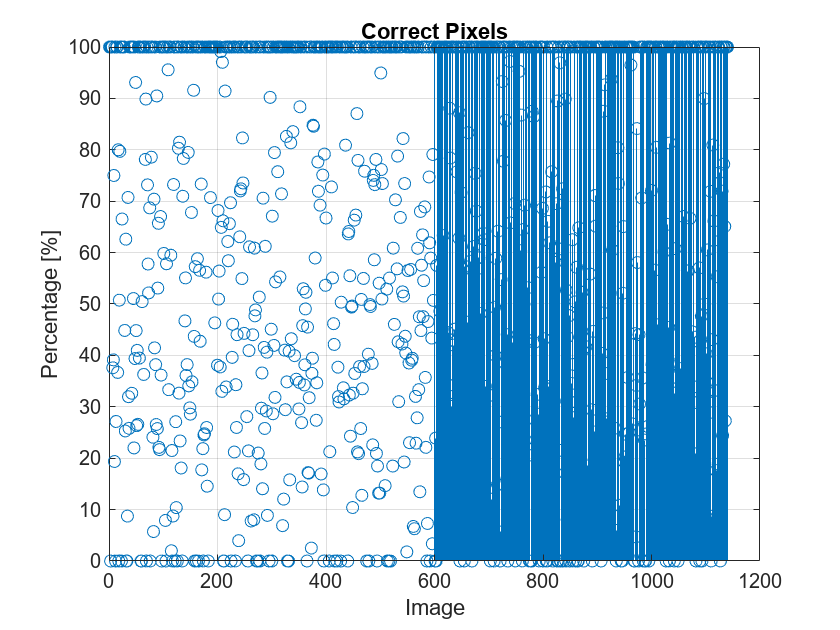


% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics

figure;
stem(accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);% Save current figure
close(gcf);% Close figure to avoid memory usage
figure;
stem(precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);


overall_correct_landslide = 64.5593

overall_precision = mean(precision)*100;

overall_precision = 0.2307

overall_recall = mean(recall)*100;

overall_pix_precision = 0.2307

overall_recall = 0.1632

overall_f1_score = mean(f1_score)*100;

overall_pix_recall = 0.1632

overall_f1_score = 0.1721

overall_accuracy= mean(accuracy)*100;

overall_pix_f1_score = 0.1721

overall_accuracy = 0.9709

overall_pix_accuracy = 0.9709

t4 = datetime('now')

t4 = datetime
   23-Mar-2025 17:05:41


elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

Total time: 11790.9s


% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- GLCM SVM Sense No Morphology -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all;

### GLCM with SVM - 5 Opening

#### Sense Dataset

imgs_proc = 0;
  
% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\5_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';
output_svm_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));
fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

% Go through through folder
t1 = datetime('now')

% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images
list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels
list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images
list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Load SVM
load(fullfile(output_svm_dir, 'SVMIris.mat'));
load(fullfile(output_svm_dir, 'svm_landslide_model.mat'));

% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        mask = imopen(mask, strel('disk', 5)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end
        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now')
elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics
figure;
stem(accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);% Save current figure
close(gcf);% Close figure to avoid memory usage
figure;
stem(precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision = mean(precision)*100;
overall_recall = mean(recall)*100;
overall_f1_score = mean(f1_score)*100;
overall_accuracy= mean(accuracy)*100;

t4 = datetime('now')
elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- GLCM SVM Sense 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all;

### GLCM with SVM - 7 Opening

#### Sense Dataset

imgs_proc = 0;
  
% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\7_Opening';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';
output_svm_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)

folder_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data'

% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));

Training set: 2659 images, 2659 masks


fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

Testing set: 1140 images, 1140 masks



% Go through through folder
t1 = datetime('now')

t1 = datetime
   02-Apr-2025 01:05:00



% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images

list_train_imgs = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels

list_train_lbls = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images

list_test_imgs = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre

list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

list_test_lbls = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre


% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []


features =

     []



window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Load SVM
load(fullfile(output_svm_dir, 'SVMIris.mat'));
load(fullfile(output_svm_dir, 'svm_landslide_model.mat'));

% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        mask = imopen(mask, strel('disk', 7)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end
        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t2 = datetime
   02-Apr-2025 01:05:01



t3 = datetime('now')

t3 = datetime
   02-Apr-2025 01:16:17


elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 675.6s

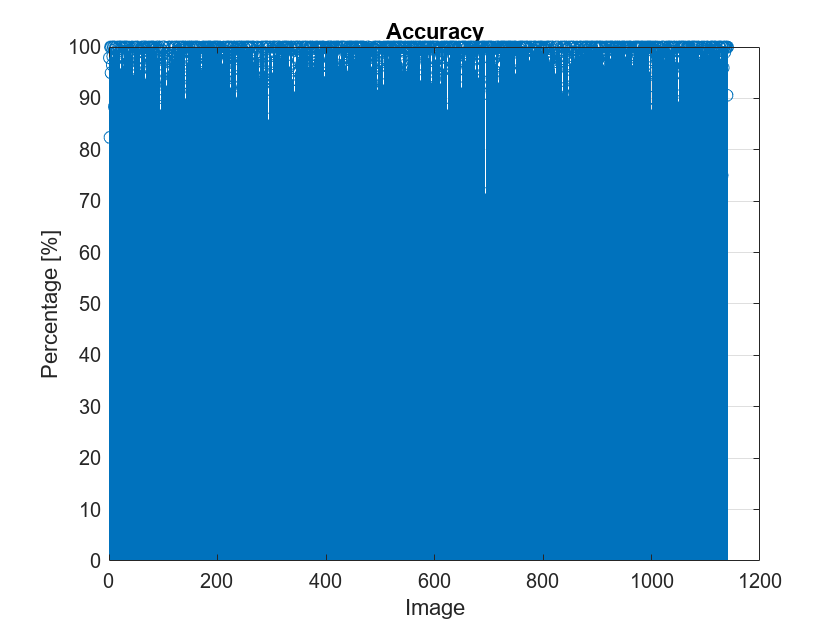


% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics
figure;
stem(accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);% Save current figure

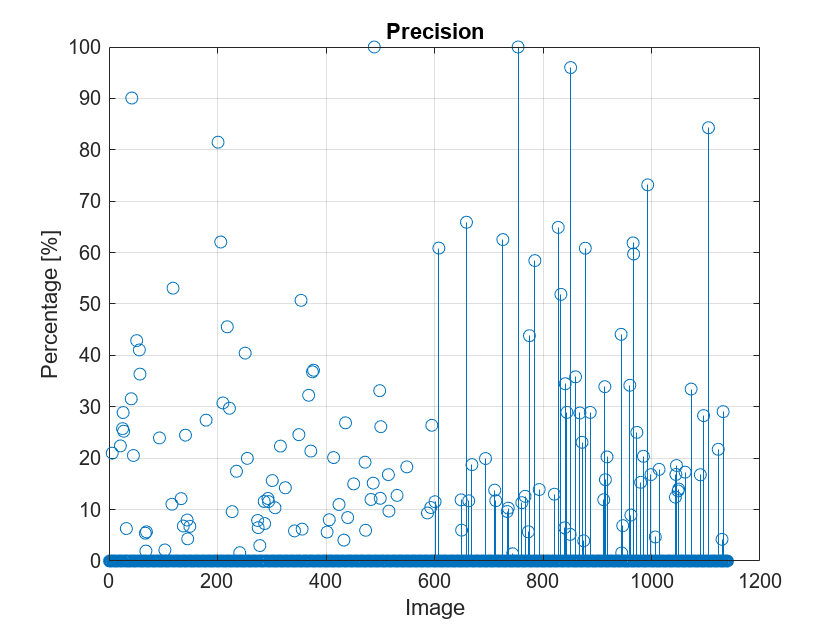

close(gcf);% Close figure to avoid memory usage
figure;
stem(precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);

close(gcf);
figure;
stem(recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision = mean(precision)*100;
overall_recall = mean(recall)*100;
overall_f1_score = mean(f1_score)*100;
overall_accuracy= mean(accuracy)*100;

t4 = datetime('now')

t4 = datetime
   02-Apr-2025 01:16:22


elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

Total time: 681.6s


% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- GLCM SVM Sense 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all;

### GLCM with SVM - 5 Closing

#### Sense Dataset

imgs_proc = 0;
  
% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\5_Closing';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';
output_svm_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)
% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));
fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

% Go through through folder
t1 = datetime('now')

% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images
list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels
list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images
list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Load SVM
load(fullfile(output_svm_dir, 'SVMIris.mat'));
load(fullfile(output_svm_dir, 'svm_landslide_model.mat'));

% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        mask = imclose(mask, strel('disk', 5)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end
        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now')
elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics
figure;
stem(accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);% Save current figure
close(gcf);% Close figure to avoid memory usage
figure;
stem(precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision = mean(precision)*100;
overall_recall = mean(recall)*100;
overall_f1_score = mean(f1_score)*100;
overall_accuracy= mean(accuracy)*100;

t4 = datetime('now')
elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- GLCM SVM Sense 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all;

### GLCM with SVM - 7 Closing

#### Sense Dataset

imgs_proc = 0;
  
% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\7_Closing';
%output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\data\Stats_classical_methods.txt';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\Stats_classical_methods.txt';
output_svm_dir = 'C:\Users\andre\EE581-LandlideProj\data\glcm_svm\Sense\';

[folder_stats_dir, ~, ~] = fileparts(output_stats_dir)

folder_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods'

% Create folder for stats outputs
if ~exist(fullfile(folder_stats_dir, 'dir'))
    mkdir(folder_stats_dir); % Create folder if doesn't exist
end


% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Paths to img and mask folders
img_dir = fullfile(orig_dir, 'img');
mask_dir = fullfile(orig_dir, 'mask');

% Get file lists
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

list_imgs_names = {list_imgs.name};
list_lbls_names = {list_lbls.name};

% Ensure they are sorted or correctly paired
list_imgs_names = sort(list_imgs_names);
list_lbls_names = sort(list_lbls_names);

% Check if the number of images and masks match
if length(list_imgs_names) ~= length(list_lbls_names)
    error('Mismatch between number of images and masks');
end

% Shuffle indices
num_files = length(list_imgs_names);
rand_indices = randperm(num_files); % Randomize order

% Split indices into 70% train, 30% test
split_ratio = 0.7;
train_count = round(split_ratio * num_files);
train_indices = rand_indices(1:train_count);
test_indices = rand_indices(train_count+1:end);

% Create training and testing lists
train_imgs_names = list_imgs_names(train_indices);
train_lbls_names = list_lbls_names(train_indices);
test_imgs_names = list_imgs_names(test_indices);
test_lbls_names = list_lbls_names(test_indices);

% Display counts
fprintf('Training set: %d images, %d masks\n', length(train_imgs_names), length(train_lbls_names));

Training set: 2659 images, 2659 masks


fprintf('Testing set: %d images, %d masks\n', length(test_imgs_names), length(test_lbls_names));

Testing set: 1140 images, 1140 masks



% Go through through folder
t1 = datetime('now')

t1 = datetime
   02-Apr-2025 00:42:07



% Get list of image and label files
list_train_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), train_imgs_names, 'UniformOutput', false) % Get images

list_train_imgs = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_train_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), train_lbls_names, 'UniformOutput', false) % Get labels

list_train_lbls = 1×2659 cell array
  Columns 1 through 1310

    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}    {'C:\Users\andre\…'}  

list_test_imgs = cellfun(@(f) fullfile(orig_dir, 'img', f), test_imgs_names, 'UniformOutput', false) % Get images

list_test_imgs = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre

list_test_lbls = cellfun(@(f) fullfile(orig_dir, 'mask', f), test_lbls_names, 'UniformOutput', false) % Get labels

list_test_lbls = 1×1140 cell array
    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre\Yea…'}    {'C:\Users\andre


% Set up stats storage
% Assign zero array of its image count
% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_test_imgs));
    false_pos = zeros(1,numel(list_test_imgs));
    true_neg = zeros(1,numel(list_test_imgs));
    false_neg = zeros(1,numel(list_test_imgs));
    precision = zeros(1,numel(list_test_imgs));
    recall = zeros(1,numel(list_test_imgs));
    f1_score = zeros(1,numel(list_test_imgs));
    accuracy = zeros(1,numel(list_test_imgs));
end

% Init
features = []


features =

     []



window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Load SVM
load(fullfile(output_svm_dir, 'SVMIris.mat'));
load(fullfile(output_svm_dir, 'svm_landslide_model.mat'));

% Ensure corresponding images and labels exist
if numel(list_test_imgs) ~= numel(list_test_lbls)
    warning('Mismatch in image-label count');
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now')
    t3 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'), 'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end
    for k = 1:numel(list_test_imgs)

        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = list_train_imgs{k};
        lbl_path = list_train_lbls{k};

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);

        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise label
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into RGB, normalise, and convert to grayscale
        img = double(cat(3, R_CH, G_CH, B_CH));
        if max(img(:)) > 0
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
        end

        img_gray = rgb2gray(img);

        [rows, cols] = size(img_gray); % Img dimens

        mask = zeros(rows, cols);
        % Slide over img with 10x10 window
        for r = 1:window_size:rows-window_size+1
            for c = 1:window_size:cols-window_size+1
                % Extract window
                window = img_gray(r:r+window_size-1, c:c+window_size-1);

                % Compute GLCM features
                glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
                stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'});

                % Store features
                features = [mean(stats.Contrast), mean(stats.Correlation), ...
                    mean(stats.Energy), mean(stats.Homogeneity),];
                features(isnan(features)) = 0;

                % Predict Landlside or not
                predLabel = predict(svmModel, features);

                % Store result in mask
                mask(r:r+window_size-1,c:c+window_size-1) = predLabel; % Mark landlside area
            end
        end
        mask = imclose(mask, strel('disk', 7)); % Fill gaps

        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end
        mask_name = split(test_imgs_names{k}, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t2 = datetime
   02-Apr-2025 00:42:08



t3 = datetime('now')

t3 = datetime
   02-Apr-2025 00:53:23


elapsedTime = seconds(t3-t2); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 675.6s

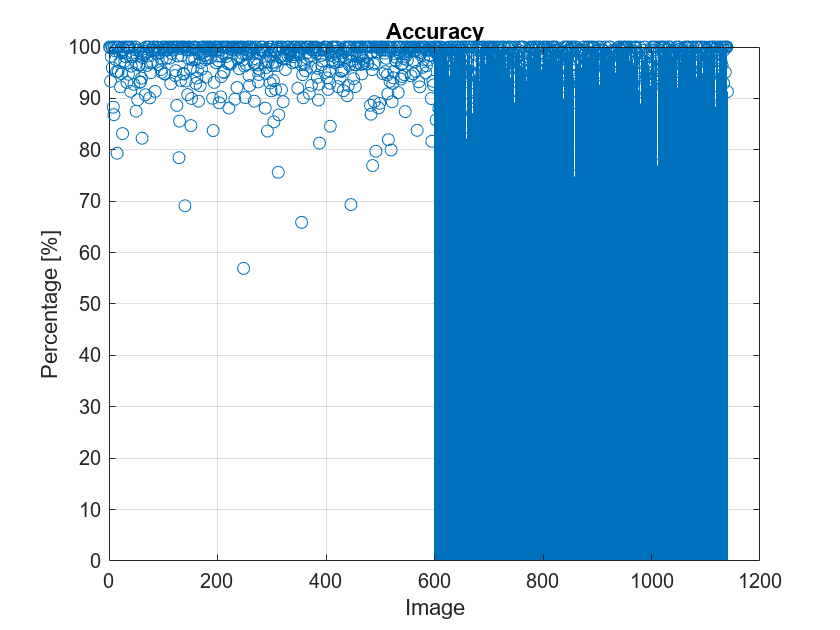


% Create folder to output plots
if ~exist(fullfile(output_dir,'Plots'), 'dir')
    mkdir(output_dir,'Plots');
end

% Plot statistics
figure;
stem(accuracy*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Accuracy");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Accuracy.png');
saveas(gcf, output_file);% Save current figure

close(gcf);% Close figure to avoid memory usage
figure;
stem(precision*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Precision");
grid on;
ylim([0 100]);
output_file = fullfile(output_dir,'Plots','Precision.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(recall*100);
xlabel('Image');
ylabel('Percentage [%]');
title("Recall");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','Recall.png');
saveas(gcf, output_file);
close(gcf);
figure;
stem(f1_score*100);
xlabel('Image');
ylabel('Percentage [%]');
title("F1 Score");
ylim([0 100]);
grid on;
output_file = fullfile(output_dir,'Plots','F1_Score.png');
saveas(gcf, output_file);
close(gcf);

overall_precision = mean(precision)*100;

overall_precision = 0.2111

overall_recall = mean(recall)*100;

overall_recall = 0.1634

overall_f1_score = mean(f1_score)*100;

overall_f1_score = 0.1613

overall_accuracy= mean(accuracy)*100;

overall_accuracy = 0.9679


t4 = datetime('now')

t4 = datetime
   02-Apr-2025 00:53:28


elapsedTime = seconds(t4-t1); % Cacluate elapsed times
fprintf("Total time: %.1fs", elapsedTime);    

Total time: 680.6s


% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- GLCM SVM Sense 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'Precision = %.5f\n', overall_precision);
fprintf(output_stats_id, 'Recall = %.5f\n', overall_recall);
fprintf(output_stats_id, 'F1 score = %.5f\n', overall_f1_score);
fprintf(output_stats_id, 'Accuracy  = %.5f\n', overall_accuracy);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all;